% Reading Data 
data = readtable("Train_reviews.csv")

data = 24984×2 table
                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                   

summary(data)

Variables:

    Text_Review: 24984×1 cell array of character vectors

    Sentiment: 24984×1 cell array of character vectors



Text  = data.Text_Review;
% Tokenizing our text data 
cleanedDocuments = tokenizedDocument(Text);
cleanedDocuments(1:10)

ans =   10×1 tokenizedDocument:

    189 tokens: bromwell high is a cartoon comedy . it ran at the same time as some other programs about school life , such as " teachers " . my 35 years in the teaching profession lead me to believe that bromwell high \ ' s satire is much closer to reality than is " teachers " . the scramble to survive financially , the insightful students who can see right through their pathetic teachers \ ' pomp , the pettiness of the whole situation , all remind me of the schools i knew and their students . when i saw the episode in which a student repeatedly tried to burn down the school , i immediately recalled . . . . . . . . . at . . . . . . . . . . high . a classic line : inspector : i \ ' m here to sack one of your teachers . student : welcome to bromwell high . i expect that many adults of my age think that bromwell high is far fetched . what a pity that it isn \ ' t !
    517 tokens: h

% To improve lemmatization, add part of speech details to the documents using addPartOfSpeechDetails
cleanedDocuments = addPartOfSpeechDetails(cleanedDocuments);
cleanedDocuments(1:10)

ans =   10×1 tokenizedDocument:

    172 tokens: bromwell high is a cartoon comedy . it ran at the same time as some other programs about school life , such as " teachers " . my 35 years in the teaching profession lead me to believe that bromwell high \ ' s satire is much closer to reality than is " teachers " . the scramble to survive financially , the insightful students who can see right through their pathetic teachers \ ' pomp , the pettiness of the whole situation , all remind me of the schools i knew and their students . when i saw the episode in which a student repeatedly tried to burn down the school , i immediately recalled ......... at .......... high . a classic line : inspector : i \ ' m here to sack one of your teachers . student : welcome to bromwell high . i expect that many adults of my age think that bromwell high is far fetched . what a pity that it isn \ ' t !
    516 tokens: homelessness ( or 

% Removing stop words 
cleanedDocuments = removeStopWords(cleanedDocuments);
cleanedDocuments(1:10)

ans =   10×1 tokenizedDocument:

    104 tokens: bromwell high cartoon comedy . ran same time programs school life , " teachers " . 35 years teaching profession lead believe bromwell high \ ' s satire closer reality " teachers " . scramble survive financially , insightful students right pathetic teachers \ ' pomp , pettiness whole situation , remind schools knew students . saw episode student repeatedly tried burn down school , immediately recalled ......... .......... high . classic line : inspector : \ ' m sack teachers . student : welcome bromwell high . expect many adults age think bromwell high far fetched . pity isn \ ' t !
    294 tokens: homelessness ( houselessness george carlin stated ) issue years never plan help street once considered human everything going school , work , vote matter . people think homeless just lost cause worrying things racism , war iraq , pressuring kids succeed , technology , ele

% Lematizing using normalize words
cleanedDocuments = normalizeWords(cleanedDocuments,'Style','lemma');
cleanedDocuments(1:10)

ans =   10×1 tokenizedDocument:

    104 tokens: bromwell high cartoon comedy . run same time program school life , " teacher " . 35 year teaching profession lead believe bromwell high \ ' s satire close reality " teacher " . scramble survive financially , insightful student right pathetic teacher \ ' pomp , pettiness whole situation , remind school know student . see episode student repeatedly try burn down school , immediately recall ......... .......... high . classic line : inspector : \ ' m sack teacher . student : welcome bromwell high . expect many adult age think bromwell high far fetch . pity isn \ ' t !
    294 tokens: homelessness ( houselessness george carlin state ) issue year never plan help street once consider human everything go school , work , vote matter . people think homeless just lost cause worry thing racism , war iraq , pressure kid succeed , technology , election , inflation , worry \ ' l

% Removing  Punctuations 
cleanedDocuments = erasePunctuation(cleanedDocuments);
cleanedDocuments(1:10)

ans =   10×1 tokenizedDocument:

     73 tokens: bromwell high cartoon comedy run same time program school life teacher 35 year teaching profession lead believe bromwell high s satire close reality teacher scramble survive financially insightful student right pathetic teacher pomp pettiness whole situation remind school know student see episode student repeatedly try burn down school immediately recall high classic line inspector m sack teacher student welcome bromwell high expect many adult age think bromwell high far fetch pity isn t
    216 tokens: homelessness houselessness george carlin state issue year never plan help street once consider human everything go school work vote matter people think homeless just lost cause worry thing racism war iraq pressure kid succeed technology election inflation worry ll next end up street bet live street month luxury once home entertainment set bathroom picture wall compu

% Removing numbers and other expressions
cleanedDocuments=regexprep(cleanedDocuments,'[^A-Za-z\'']','')

cleanedDocuments =   24984×1 tokenizedDocument:

      72 tokens: bromwell high cartoon comedy run same time program school life teacher year teaching profession lead believe bromwell high s satire close reality teacher scramble survive financially insightful student right pathetic teacher pomp pettiness whole situation remind school know student see episode student repeatedly try burn down school immediately recall high classic line inspector m sack teacher student welcome bromwell high expect many adult age think bromwell high far fetch pity isn t
     216 tokens: homelessness houselessness george carlin state issue year never plan help street once consider human everything go school work vote matter people think homeless just lost cause worry thing racism war iraq pressure kid succeed technology election inflation worry ll next end up street bet live street month luxury once home entertainment set bathroom pic

cleanedDocuments = removeLongWords(cleanedDocuments,12);
cleanedDocuments = removeShortWords(cleanedDocuments,3); 
cleanedDocuments(1:10)

ans =   10×1 tokenizedDocument:

     63 tokens: bromwell high cartoon comedy same time program school life teacher year teaching profession lead believe bromwell high satire close reality teacher scramble survive financially insightful student right pathetic teacher pomp pettiness whole situation remind school know student episode student repeatedly burn down school immediately recall high classic line inspector sack teacher student welcome bromwell high expect many adult think bromwell high fetch pity
    176 tokens: george carlin state issue year never plan help street once consider human everything school work vote matter people think homeless just lost cause worry thing racism iraq pressure succeed technology election inflation worry next street live street month luxury once home bathroom picture wall computer everything once treasure like homeless goddard bolt lesson brook direct star bolt play rich everyth

% Bag of Words
 bag = bagOfWords(cleanedDocuments)

bag =   bagOfWords with properties:

          Counts: [24984×65099 double]
      Vocabulary: ["bromwell"    "high"    "cartoon"    "comedy"    "same"    "time"    "program"    "school"    "life"    "teacher"    "year"    "teaching"    "profession"    "lead"    "believe"    "satire"    "close"    "reality"    …    ]
        NumWords: 65099
    NumDocuments: 24984


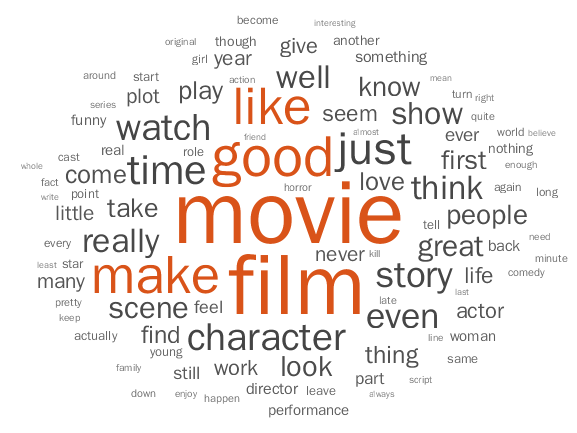

ans =   WordCloudChart with properties:

           WordData: ["movie"    "film"    "good"    "make"    "like"    "just"    "time"    "character"    "watch"    "story"    "even"    "think"    "really"    "well"    "show"    "scene"    "great"    "look"    "people"    "know"    "first"    …    ]
           SizeData: [50951 47186 25470 22339 21835 17741 15445 14060 13505 12949 12626 11775 11725 11298 10719 10459 9965 9766 9365 9253 8904 8632 8516 8353 8199 8188 7975 7319 7192 6996 6868 6797 6723 6659 6485 6438 6410 5889 5718 5658 5176 5034 … ]
    MaxDisplayWords: 100

  Show all properties


figure 
wordcloud(bag)

bag = removeInfrequentWords(bag,40)

bag =   bagOfWords with properties:

          Counts: [24984×6126 double]
      Vocabulary: ["high"    "cartoon"    "comedy"    "same"    "time"    "program"    "school"    "life"    "teacher"    "year"    "teaching"    "profession"    "lead"    "believe"    "satire"    "close"    "reality"    "survive"    …    ]
        NumWords: 6126
    NumDocuments: 24984


ans =   WordCloudChart with properties:

           WordData: ["movie"    "film"    "good"    "make"    "like"    "just"    "time"    "character"    "watch"    "story"    "even"    "think"    "really"    "well"    "show"    "scene"    "great"    "look"    "people"    "know"    "first"    …    ]
           SizeData: [50951 47186 25470 22339 21835 17741 15445 14060 13505 12949 12626 11775 11725 11298 10719 10459 9965 9766 9365 9253 8904 8632 8516 8353 8199 8188 7975 7319 7192 6996 6868 6797 6723 6659 6485 6438 6410 5889 5718 5658 5176 5034 … ]
    MaxDisplayWords: 100

  Show all properties


figure 
wordcloud(bag)

most_common = topkwords(bag,50)

most_common = 50×2 table
       Word        Count
    ___________    _____

    "movie"        50951
    "film"         47186
    "good"         25470
    "make"         22339
    "like"         21835
    "just"         17741
    "time"         15445
    "character"    14060
    "watch"        13505
    "story"        12949
    "even"         12626
    "think"        11775
    "really"       11725
    "well"         11298
    "show"         10719
    "scene"        10459


data.Text_Review = cleanedDocuments.joinWords;
data

data = 24984×2 table
                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        Text_Review                                                                                                                                                                                                               

writematrix(table2array(data),'Process_train.csv');